clc
clear all

TSST = readtable('SST.xlsx');

T = readtable('srca.xlsx','Sheet','endpoint');
%%Sr/Ca monthly interpolation for 1671.583 - 2007.583
T.SrCa(T.SrCa == 0) = nan;
T.RSD(T.RSD == 0) = nan;
Year = flip(fillmissing(T.Winters,"linear","SamplePoints",T.Depth)); %fill gap and flip
SrCa = flip(T.SrCa); %flip first to match age model
SrCaerror = flip(T.RSD).*SrCa/100;
[SrCa,~] = fillmissing(SrCa,"linear","SamplePoints",Year); %fill gap 
[SrCaerror,~] = fillmissing(SrCaerror,"linear","SamplePoints",Year);
yearsst = [(1671+1/12*7):1/12:(2007+1/12*7)]'; %1671.583 - 2007.583
srcamonthly = interp1(Year,SrCa,yearsst,'linear',"extrap");
srcaerrorindividual = interp1(Year,SrCaerror,yearsst,'linear',"extrap");
srcaerrlongterm = 0.006;
srcaerrormonthly = sqrt(srcaerrorindividual.^2+srcaerrlongterm^2);

depth = T.Depth;
N = T.Winters;
[index,yr] = find(~isnan(N));
AER=diff(depth(index)); %annual extension rate
AER = flip(AER);
yr = (1672:2007)'; %annual mean extenison rate and Sr/Ca 1672 = 1671 August to 1672 July
gap = (1:12:4033)';
ASrCa=zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=srcamonthly(gap(i):(gap(i+1)-1));
    ASrCa(i) = mean(t,'omitnan');
i=i+1;
end


% test AER and Sr/Ca relationship
[r,p] = corr(ASrCa(281:end),AER(281:end))

r = -0.2393

p = 0.0757


k=1 %monthly sampling frequency 1 samples a year 

k = 1

%cutoff frequency K month = 1/K samples/yr 
[m1,n1]=butter(5,(1/5)/(0.5*k),'low');
ASrCa_LPF = filtfilt(m1,n1,ASrCa);
AER_LPF = filtfilt(m1,n1,AER);
[r p] = corr(ASrCa_LPF(281:end), AER_LPF(end-55:end))

r = -0.3990

p = 0.0023

n =length(ASrCa_LPF(281:end));
r1 = autocorr(ASrCa_LPF(281:end),1);
r1= r1(2);
r2=autocorr(ASrCa_LPF(end-55:end),1);
r2 = r2(2);
nadj = n.*(1-r1.*r2)./(1+r1.*r2)

nadj = 8.1940

t_stat = r * sqrt((nadj - 2) / (1 - r^2))

t_stat = -1.0830

p = 2 * (1 - tcdf(abs(t_stat), nadj - 2)) 

p = 0.3192

%Figure
clf

yyaxis right
hold on
plot(yr,AER,'LineWidth',1)
ylabel('AER (mm/yr)')
set(gca,'ylim',[0 30])

yyaxis left
plot(yr,ASrCa,'LineWidth',1)
plot(yearsst,srcamonthly,'-')
ylabel('Sr/Ca ratio (mmol/mol)')
set(gca, 'ydir','reverse')
set(gca,'xlim',[1951 2008])
xlabel('Year')
box on 
lg=legend ('Annual mean Sr/Ca','monthly Sr/Ca','Annual linear extension rate')

lg =   Legend (Annual mean Sr/Ca, monthly Sr/Ca, Annual linear extension rate) with properties:

         String: {'Annual mean Sr/Ca'  'monthly Sr/Ca'  'Annual linear extension rate'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6188 0.8155 0.2723 0.0905]
          Units: 'normalized'

  Show all properties


set(lg,'box','off','Location','best')

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

%%Load instrumental SST records
HadISST = TSST.HadISST;
ERSSTv5 = TSST.ERSSTv5;
OISSTv2 = TSST.OISSTv2;
OISSTv2error = TSST.OISSTv2error;
ICOADS=TSST.ICOADS;
CCI = TSST.CCI;
CCIerror = TSST.CCIerror;
Date = TSST.Date;
TSST.Mon = categorical(TSST.Mon);

clf
%figure
time=datetime(1800,1,15)+calmonths(ncread("icoads_sst_n_48-56E_-16--8N_n.nc",'time'));
observatonNo=ncread('icoads_sst_n_48-56E_-16--8N_n.nc','sst');
index0 = observatonNo==0;
index1 = observatonNo>1;
index2 = observatonNo>5;
hold on 
plot(time(index0),observatonNo(index0),'.','MarkerSize',12)
plot(time(index1),observatonNo(index1),'.','MarkerSize',12)
plot(time(index2),observatonNo(index2),'.','MarkerSize',12)

set(gca,'xlim',[datetime(1870,1,1), datetime(2009,1,1)])
set(gca,'ylim',[0 30])
xlabel('Year')
ylabel('ICOADS SST bservation No.')
legend({'Months with no observation','Months with at least 1 observation','Months with more than 5 observations'})
set(legend,'Box','off')
box on

gap = (4:12:4024)';
yr = (1672:2006)';
% year 2006 = 2005.11-2006.10


AERSST = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=ERSSTv5(gap(i):(gap(i+1)-1));
    AERSST(i) = mean(t,'omitnan');
i=i+1;
end

AHadISST = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=HadISST(gap(i):(gap(i+1)-1));
    AHadISST(i) = mean(t,'omitnan');
i=i+1;
end

AOISST = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=OISSTv2(gap(i):(gap(i+1)-1));
    AOISST(i) = mean(t,'omitnan');
i=i+1;
end


ACCI = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=CCI(gap(i):(gap(i+1)-1));
    ACCI(i) = mean(t,'omitnan');
i=i+1;
end


AOISST_Err = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=OISSTv2error(gap(i):(gap(i+1)-1));
    AOISST_Err(i) = rms(t,'omitnan');
i=i+1;
end

ACCI_Err = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=CCIerror(gap(i):(gap(i+1)-1));
    ACCI_Err(i) = rms(t,'omitnan');
i=i+1;
end


clf
%figure
hold on


errordate = vertcat(Date(3722:end),flipud(Date(3722:end)));
oisstUncertainties = vertcat(OISSTv2(3722:end)+OISSTv2error(3722:end),flipud(OISSTv2(3722:end)-OISSTv2error(3722:end)));
cciUncertainties = vertcat(CCI(3722:end)+CCIerror(3722:end),flipud(CCI(3722:end)-CCIerror(3722:end)));
patch(errordate,oisstUncertainties,[0.8500 0.3250 0.0980],'Edgecolor','none','Facealpha',0.4)
patch(errordate,cciUncertainties,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.4)

Apatch_date = vertcat(yr(310:end),flipud(yr(310:end)));
ACCI_unc = vertcat(ACCI(310:end)+ACCI_Err(310:end),flipud(ACCI(310:end)-ACCI_Err(310:end)));
AOISST_unc = vertcat(AOISST(310:end)+AOISST_Err(310:end),flipud(AOISST(310:end)-AOISST_Err(310:end)));
patch(Apatch_date+0.5,AOISST_unc,[0.8500 0.3250 0.0980],'Edgecolor','none','Facealpha',0.4)
patch(Apatch_date+0.5,ACCI_unc,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.4)


plot(Date,CCI)
plot(Date,OISSTv2)
plot(Date,HadISST)
plot(Date,ERSSTv5)

plot(yr+0.5,ACCI,'Color',[0 0.4470 0.7410],'LineWidth',1)
plot(yr+0.5,AOISST,'Color',[0.8500 0.3250 0.0980],'LineWidth',1)
plot(yr+0.5,AHadISST,'Color',[0.9290, 0.6940, 0.1250],'LineWidth',1)
plot(yr+0.5,AERSST,'Color',[0.4940, 0.1840, 0.5560],'LineWidth',1)
set(gca,'Xlim',[1951.58 2007.59])
set(gca,'Ylim',[23 30])
box on
lg = legend('','','','','CCI','OISSTv2','HadISST1','ERSSTv5','Location','best')

lg =   Legend (CCI, OISSTv2, HadISST1, ERSSTv5) with properties:

         String: {'CCI'  'OISSTv2'  'HadISST1'  'ERSSTv5'}
       Location: 'best'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.3474 0.1326 0.1464 0.1179]
          Units: 'normalized'

  Show all properties


set(lg,'box','off')
ylabel('SST (°C)')
hold off

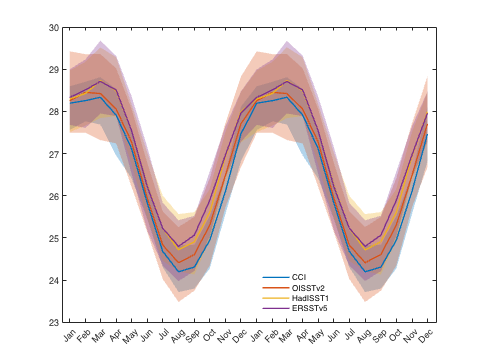

Seasons= readtable("Seasonality.xlsx",'Sheet','SST 91_00');
Seasonality = Seasons(:,[1,2,8,14,11]);
seasonerror = Seasons(:,[1,3,4,9,10,15,16,12,13]);
Seasonality.Mon = [datetime(2008,01,15):calmonths(1):datetime(2009,12,15)]';
Seasonality = table2timetable(Seasonality);
sCCI = vertcat(seasonerror.CCIl,flipud(seasonerror.CCIu));
sOISST = vertcat(seasonerror.OISSTl,flipud(seasonerror.OISSTu));
sERSST = vertcat(seasonerror.ERSSTl,flipud(seasonerror.ERSSTu));
sHadISST = vertcat(seasonerror.HadISSTl,flipud(seasonerror.HadISSTu));
seasonMon = vertcat(seasonerror.Mon,flipud(seasonerror.Mon));
seasonMon = vertcat(Seasonality.Mon,flipud(Seasonality.Mon));
clf
hold on
patch(seasonMon,sCCI,[0, 0.4470, 0.7410],'Edgecolor','none','Facealpha',0.3)
patch(seasonMon,sOISST,[0.8500, 0.3250, 0.0980],'Edgecolor','none','Facealpha',0.3)
patch(seasonMon,sHadISST,[0.9290, 0.6940, 0.1250],'Edgecolor','none','Facealpha',0.3)
patch(seasonMon,sERSST,[0.4940, 0.1840, 0.5560],'Edgecolor','none','Facealpha',0.3)

h=plot(Seasonality.Mon,Seasonality.Variables,'LineWidth',1.5);
legend('','','','','CCI','OISSTv2','HadISST1','ERSSTv5','Location','best')
xticks(datetime(2008,01,15):calmonths(1):datetime(2009,12,15))
xticklabels({'Jan','Feb','Mar','Apr','May','Jun','Jul','Aug','Sep','Oct','Nov','Dec','Jan','Feb','Mar','Apr','May','Jun','Jul','Aug','Sep','Oct','Nov','Dec'})
box on
set(legend,'box','off')


% If using OISSTv2 for calibration:

k1 = find(OISSTv2>0);
k1 = k1(1);
tic

tol = 1e-8;    % Tolerance
X = OISSTv2(k1:end)-mean(OISSTv2(k1:end));
sigX = OISSTv2error(k1:end);
Y = srcamonthly(k1:end)-mean(srcamonthly(k1:end));
sigY = srcaerrormonthly(k1:end);


%% Simple Linear Regression
% Performs simple linear regression (SLR) for comparison.

R = corrcoef(X,Y);
n = length(X);

ri = 0;
X1 = [n,sum(X);sum(X),sum(X.*X)];               % LSE Value of 'b'
Y1 = [sum(Y);sum(X.*Y)];                        % Polyfit can also be used
Z1 = X1\Y1;                                     % Matrix division
a1 = Z1(1);
b1 = Z1(2);

sigres = sum((Y - a1 - b1.*X).^2)/(n-2);        % Sigma Residual  s^2
delta = det(X1);  % Determinant              = n*(n-1)*varx 
varx = var(X);
sigb1sq = (n^2)*(n-1)*varx*sigres/(delta^2);    % Sigma(b) without weights
sigb1 = sqrt(sigb1sq); % standard error of slope 
Xbar = mean(X);

%siga1sq = (sigres/(varx*n))*(varx + Xbar^2) 
siga1sq = sigres*(1/n + Xbar^2/varx/(n-1)); 
siga1 = sqrt(siga1sq); % standard error of intercept
A_SLR = [a1 siga1];                             % SLR Intercept
B_SLR = [b1 sigb1];                            % SLR Slope

%---- SLR p-value ----

B1 = 0;
t1=(b1-B1)/sigb1;    % t = (m - m0)/SE
Pval1=2*(1-tcdf(abs(t1),n-2)); %?

%% 4. Maximum Likelihood Method (Weighted Linear Regression)
% Implements the _York et al._ [200.00104] algorithm to perform weighted linear
% regression using the maximum likelihood method (MLM).

%---- Weighting Errors ----

wX = abs(1./(sigX.^2));                     %weights w = 1/sig^2
wY = abs(1./(sigY.^2));
alpha = sqrt(wX.*wY);
%ri = mat(:,5);         % CorrCoef between sig(X) and sig(Y)

b = b1;                             
d = tol;                            
i = 0; 

%---- York et al. (2004) Algorithm ----

while (d > tol || d == tol)         % Tolerance check loop
    i = i+1;
    b2 = b;
    W = wX.*wY./((wX) + ((b^2).*wY) - (2.*b.*alpha.*ri));
    meanX = sum(W.*X)/sum(W);       %weighted mean
    meanY =  sum(W.*Y)/sum(W);      
    U = X(:) - meanX;
    V = Y(:) - meanY;
    Beta = W.*((U./wY)+((b.*V)./wX) - (b.*U + V).*(ri./alpha));
    meanBeta = sum(W.*Beta)/sum(W);
    b = sum(W.*Beta.*V)/sum(W.*Beta.*U);
    dif = b - b2;
    d = abs(dif);
end

U2 = U.^2;
V2 = V.^2;
a = meanY - b.*meanX;
x = meanX + Beta;
meanx = sum(W.*x)/sum(W);
u = x - meanx;
sigbsq = 1./(sum(W.*(u.*u)));
sigb = sqrt(sigbsq);
sigasq = 1./(sum(W)) + meanx^2.*(sigbsq);
siga = sqrt(sigasq);
S = sum(W.*((Y - b.*X - a)).^2);

%---- MLE p-value ----
B = 0;
t=(b-B)/sigb;
Pval=2*(1-tcdf(abs(t),length(X)-2));


%%RMA method
[rb,bintr,bintjm] = gmregress(X,Y,0.05);
B_RMA =  [rb(2),(bintr(2,2)-bintr(2,1))/3.92];
A_RMA = [rb(1), (bintr(1,2)-bintr(1,1))/3.92];

SSR = sum((Y - (rb(2).*X + rb(1))).^2);
SST = sum((Y - mean(Y)).^2);
rb_r = -1*sqrt(1 - SSR/SST);
rb_r2 = 1 - SSR/SST;

%% 5. Plot
clf
subplot(2,3,1)
hold on;
set(gca,'FontSize',12,'FontName','Myriad Pro');
h0 = errorbar(X,Y,sigX,'horizontal','Marker','none','LineStyle','none','linewidth',0.3,'Color',[0 0 0]/256);
h1 = errorbar(X,Y,sigY,'Marker','none','LineStyle','none','linewidth',0.3,'Color',[0 0 0]/256); 
%c = uisetcolor([1 1 1])
grid on;   
plot(X,Y,'.k',MarkerSize=7)
p = min(X)-(max(X)-min(X))/10:(max(X)-min(X))/10:max(X)+(max(X)-min(X))/10;
q1 = a + (b.*p);
h2 = plot(p,q1,'linewidth',2,'Color',[0.2 0.5 1]);

q2 = rb(1)+(rb(2).*p);
h3 = plot(p,q2,'-.','LineWidth',2,'Color',[0.4 0.6 0.4]);

q3 = a1 + (b1.*p);
h4 = plot(p,q3,'--','LineWidth',2,'Color',[1 0.6 0.4]);
pl = legend([h0,h1,h2,h3,h4],'SST uncertainties','Sr/Ca uncertainties','WLS','RMA','OLS');
htext=findobj(get(pl,'children'),'type','text');
set(pl,'Box','off')
xlabel('OISSTv2 (°C)');
ylabel('Sr/Ca');
box on
xlim([-4 4])
ylim([-0.3 0.3])


 A = [a siga];
 B = [b sigb];
 disp('--------------------------------------');

--------------------------------------


display('Weighted Linear Regression:');disp(' ');

Weighted Linear Regression:
 


wr = sum(U.*V)./sqrt((sum(U2).*sum(V2)));
display('Y = a + bX');display(' ');

Y = a + bX
 


disp('       a      siga');disp(A);

       a      siga
   -0.0021    0.0008



disp('       b      sigb');disp(B);

       b      sigb
   -0.0607    0.0006



disp(['r: ',num2str(wr)]);

r: -0.84783


disp(['r^2: ',num2str(wr^2)]);

r^2: 0.71882


disp(['p-value: ',num2str(Pval)]);

p-value: 0



disp('--------------------------------------');

--------------------------------------


display('Simple Linear Regression:');disp(' ');

Simple Linear Regression:
 


display('Y = a + bX');display(' ');

Y = a + bX
 


disp('       a      siga');disp(A_SLR);

       a      siga
   -0.0000    0.0027



disp('       b      sigb');disp(B_SLR);

       b      sigb
   -0.0494    0.0018



disp(['r: ',num2str(R(1,2))]);

r: -0.84683


disp(['r^2: ',num2str(R(1,2)^2)]);

r^2: 0.71713


disp(['p-value: ',num2str(Pval1)]);

p-value: 0


disp('--------------------------------------');

--------------------------------------


disp(['Total no. of iterations: ',num2str(i)]);

Total no. of iterations: 7


toc

Elapsed time is 0.993836 seconds.



disp('--------------------------------------');

--------------------------------------


display('Reduced Major Axis Regression:');disp(' ');

Reduced Major Axis Regression:
 


display('Y = a + bX');display(' ');

Y = a + bX
 


disp('       a      siga');disp(A_RMA);

       a      siga
   1.0e-14 *

   -0.1035    0.0000



disp('       b      sigb');disp(B_RMA);

       b      sigb
   -0.0583    0.0018



disp(['r: ',num2str(rb_r)]);

r: -0.83287


disp(['r^2: ',num2str(rb_r2)]);

r^2: 0.69367


disp(['p-value: p<0.05']);

p-value: p<0.05


disp('--------------------------------------');

--------------------------------------


disp(['Total no. of iterations: ',num2str(i)]);

Total no. of iterations: 7


toc

Elapsed time is 1.013663 seconds.



%Sr/Ca-SST reconstruction if using WLS
SST_WLS = (srcamonthly-mean(srcamonthly(k1:end)))./B(1)+A(1);

%error propogation if using WLS
SD1 = (1/B(1)).*srcaerrormonthly;
SD2 = (-1/B(1))*A(2);
SD3 = (-((srcamonthly-mean(srcamonthly) - A(1))/(B(1)^2)))*B(2);
SST_err = sqrt (SD1.^2+SD2^2+SD3.^2);

%plot centred coral-derived SST and instrumental SST
SST_err2 = vertcat(SST_WLS+SST_err,flipud(SST_WLS-SST_err));
patch_date = vertcat(Date,flipud(Date));
oissterrordate = vertcat(Date(k1:end),flipud(Date(k1:end)));
oisstUncertainties = vertcat(OISSTv2(k1:end)+OISSTv2error(k1:end),flipud(OISSTv2(k1:end)-OISSTv2error(k1:end)));

ACoralSST1 = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=SST_WLS(gap(i):(gap(i+1)-1));
    ACoralSST1(i) = mean(t,'omitnan');
i=i+1;
end

ACoralSST1_Err = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=SST_err(gap(i):(gap(i+1)-1));
    ACoralSST1_Err(i) = rms(t,'omitnan');
i=i+1;
end

subplot(2,3,[2 3])
hold on

plot(Date,SST_WLS,'LineWidth',1)
plot(Date,OISSTv2-mean(OISSTv2,'omitnan'),'LineWidth',1)
patch(oissterrordate,oisstUncertainties-mean(OISSTv2,'omitnan'),[0.8500 0.3250 0.0980],'Edgecolor','none','Facealpha',0.4)
patch(patch_date,SST_err2,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.4)
plot(yr+0.5,ACoralSST1,'Color',[0 0.4470 0.7410])
plot(yr+0.5,AOISST-mean(OISSTv2,'omitnan'),'Color',[0.8500 0.3250 0.0980],'LineWidth',1)
patch(Apatch_date+0.5,AOISST_unc-mean(OISSTv2,'omitnan'),[0.8500 0.3250 0.0980],'Edgecolor','none','Facealpha',0.4)
Acoral_unc = vertcat(ACoralSST1(310:end)+ACoralSST1_Err(310:end),flipud(ACoralSST1(310:end)-ACoralSST1_Err(310:end)));
patch(Apatch_date+0.5,Acoral_unc,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.4)
patch(errordate,oisstUncertainties-mean(OISSTv2,'omitnan'),[0.8500 0.3250 0.0980],'Edgecolor','none','Facealpha',0.4)
set(gca,'Xlim',[1981+1/12*7 2008])
ylabel('temperature (°C)')
box on
lg = legend('Coral SST_{WLS}','OISSTv2','Location','best')

lg =   Legend (Coral SST_{WLS}, OISSTv2) with properties:

         String: {'Coral SST_{WLS}'  'OISSTv2'}
       Location: 'best'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6944 0.5896 0.1741 0.0738]
          Units: 'normalized'

  Show all properties


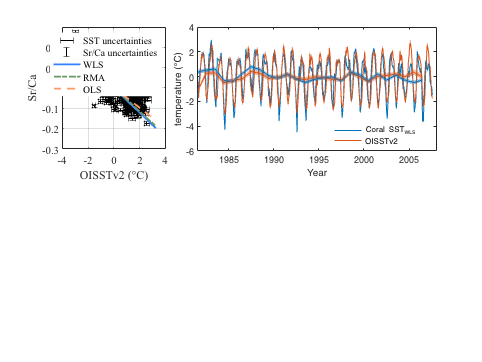

set(lg,'box','off')
xlabel('Year')

% If using CCI for calibration:

k1 = find(CCI>0);
k1 = k1(1);
tic

tol = 1e-8;    % Tolerance
X = CCI(k1:end)-mean(CCI(k1:end));
sigX = CCIerror(k1:end);
Y = srcamonthly(k1:end)-mean(srcamonthly(k1:end));
sigY = srcaerrormonthly(k1:end);


%% Simple Linear Regression
% Performs simple linear regression (SLR) for comparison.

R = corrcoef(X,Y);
n = length(X);

ri = 0;
X1 = [n,sum(X);sum(X),sum(X.*X)];               % LSE Value of 'b'
Y1 = [sum(Y);sum(X.*Y)];                        % Polyfit can also be used
Z1 = X1\Y1;                                     % Matrix division
a1 = Z1(1);
b1 = Z1(2);

sigres = sum((Y - a1 - b1.*X).^2)/(n-2);        % Sigma Residual  s^2
delta = det(X1);  % Determinant              = n*(n-1)*varx 
varx = var(X);
sigb1sq = (n^2)*(n-1)*varx*sigres/(delta^2);    % Sigma(b) without weights
sigb1 = sqrt(sigb1sq); % standard error of slope 
Xbar = mean(X);

%siga1sq = (sigres/(varx*n))*(varx + Xbar^2) 
siga1sq = sigres*(1/n + Xbar^2/varx/(n-1)); 
siga1 = sqrt(siga1sq); % standard error of intercept
A_SLR = [a1 siga1];                             % SLR Intercept
B_SLR = [b1 sigb1];                            % SLR Slope

%---- SLR p-value ----

B1 = 0;
t1=(b1-B1)/sigb1;    % t = (m - m0)/SE
Pval1=2*(1-tcdf(abs(t1),n-2)); %?

%% 4. Maximum Likelihood Method (Weighted Linear Regression)
% Implements the _York et al._ [200.00104] algorithm to perform weighted linear
% regression using the maximum likelihood method (MLM).

%---- Weighting Errors ----

wX = abs(1./(sigX.^2));                     %weights w = 1/sig^2
wY = abs(1./(sigY.^2));
alpha = sqrt(wX.*wY);
%ri = mat(:,5);         % CorrCoef between sig(X) and sig(Y)

b = b1;                             
d = tol;                            
i = 0; 

%---- York et al. (2004) Algorithm ----

while (d > tol || d == tol)         % Tolerance check loop
    i = i+1;
    b2 = b;
    W = wX.*wY./((wX) + ((b^2).*wY) - (2.*b.*alpha.*ri));
    meanX = sum(W.*X)/sum(W);       %weighted mean
    meanY =  sum(W.*Y)/sum(W);      
    U = X(:) - meanX;
    V = Y(:) - meanY;
    Beta = W.*((U./wY)+((b.*V)./wX) - (b.*U + V).*(ri./alpha));
    meanBeta = sum(W.*Beta)/sum(W);
    b = sum(W.*Beta.*V)/sum(W.*Beta.*U);
    dif = b - b2;
    d = abs(dif);
end

U2 = U.^2;
V2 = V.^2;
a = meanY - b.*meanX;
x = meanX + Beta;
meanx = sum(W.*x)/sum(W);
u = x - meanx;
sigbsq = 1./(sum(W.*(u.*u)));
sigb = sqrt(sigbsq);
sigasq = 1./(sum(W)) + meanx^2.*(sigbsq);
siga = sqrt(sigasq);
S = sum(W.*((Y - b.*X - a)).^2);

%---- MLE p-value ----
B = 0;
t=(b-B)/sigb;
Pval=2*(1-tcdf(abs(t),length(X)-2));


%%RMA method
[rb,bintr,bintjm] = gmregress(X,Y,0.05);
B_RMA =  [rb(2),(bintr(2,2)-bintr(2,1))/3.92];
A_RMA = [rb(1), (bintr(1,2)-bintr(1,1))/3.92];

SSR = sum((Y - (rb(2).*X + rb(1))).^2);
SST = sum((Y - mean(Y)).^2);
rb_r = -1*sqrt(1 - SSR/SST);
rb_r2 = 1 - SSR/SST;

%% 5. Plot

subplot(2,3,4)
hold on;
set(gca,'FontSize',12,'FontName','Myriad Pro');
h0 = errorbar(X,Y,sigX,'horizontal','Marker','none','LineStyle','none','linewidth',0.3,'Color',[0 0 0]/256);
h1 = errorbar(X,Y,sigY,'Marker','none','LineStyle','none','linewidth',0.3,'Color',[0 0 0]/256); 
%c = uisetcolor([1 1 1])
grid on;   
plot(X,Y,'.k',MarkerSize=7)
p = min(X)-(max(X)-min(X))/10:(max(X)-min(X))/10:max(X)+(max(X)-min(X))/10;
q1 = a + (b.*p);
h2 = plot(p,q1,'linewidth',2,'Color',[0.2 0.5 1]);

q2 = rb(1)+(rb(2).*p);
h3 = plot(p,q2,'-.','LineWidth',2,'Color',[0.4 0.6 0.4]);

q3 = a1 + (b1.*p);
h4 = plot(p,q3,'--','LineWidth',2,'Color',[1 0.6 0.4]);
pl = legend([h0,h1,h2,h3,h4],'SST uncertainties','Sr/Ca uncertainties','WLS','RMA','OLS');
htext=findobj(get(pl,'children'),'type','text');
set(pl,'Box','off')
xlabel('CCI (°C)');
ylabel('Sr/Ca');
box on
xlim([-4 4])
ylim([-0.3 0.3])


 A = [a siga];
 B = [b sigb];
 disp('--------------------------------------');

--------------------------------------


display('Weighted Linear Regression:');disp(' ');

Weighted Linear Regression:
 


wr = sum(U.*V)./sqrt((sum(U2).*sum(V2)));
display('Y = a + bX');display(' ');

Y = a + bX
 


disp('       a      siga');disp(A);

       a      siga
   -0.0053    0.0011



disp('       b      sigb');disp(B);

       b      sigb
   -0.0644    0.0007



disp(['r: ',num2str(wr)]);

r: -0.85009


disp(['r^2: ',num2str(wr^2)]);

r^2: 0.72266


disp(['p-value: ',num2str(Pval)]);

p-value: 0



disp('--------------------------------------');

--------------------------------------


display('Simple Linear Regression:');disp(' ');

Simple Linear Regression:
 


display('Y = a + bX');display(' ');

Y = a + bX
 


disp('       a      siga');disp(A_SLR);

       a      siga
   -0.0000    0.0028



disp('       b      sigb');disp(B_SLR);

       b      sigb
   -0.0479    0.0018



disp(['r: ',num2str(R(1,2))]);

r: -0.84078


disp(['r^2: ',num2str(R(1,2)^2)]);

r^2: 0.7069


disp(['p-value: ',num2str(Pval1)]);

p-value: 0


disp('--------------------------------------');

--------------------------------------


disp(['Total no. of iterations: ',num2str(i)]);

Total no. of iterations: 8


toc

Elapsed time is 0.323565 seconds.



disp('--------------------------------------');

--------------------------------------


display('Reduced Major Axis Regression:');disp(' ');

Reduced Major Axis Regression:
 


display('Y = a + bX');display(' ');

Y = a + bX
 


disp('       a      siga');disp(A_RMA);

       a      siga
   1.0e-14 *

   -0.1328    0.0009



disp('       b      sigb');disp(B_RMA);

       b      sigb
   -0.0570    0.0018



disp(['r: ',num2str(rb_r)]);

r: -0.82556


disp(['r^2: ',num2str(rb_r2)]);

r^2: 0.68155


disp(['p-value: p<0.05']);

p-value: p<0.05


disp('--------------------------------------');

--------------------------------------


disp(['Total no. of iterations: ',num2str(i)]);

Total no. of iterations: 8


toc

Elapsed time is 0.338061 seconds.



%Sr/Ca-SST reconstruction if using WLS
SST_WLS = (srcamonthly-mean(srcamonthly(k1:end)))./B(1)+A(1);

%error propogation if using WLS
SD1 = (1/B(1)).*srcaerrormonthly;
SD2 = (-1/B(1))*A(2);
SD3 = (-((srcamonthly-mean(srcamonthly) - A(1))/(B(1)^2)))*B(2);
SST_err = sqrt (SD1.^2+SD2^2+SD3.^2);

%plot centred coral-derived SST and instrumental SST
SST_err2 = vertcat(SST_WLS+SST_err,flipud(SST_WLS-SST_err));
patch_date = vertcat(Date,flipud(Date));

ACoralSST1 = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=SST_WLS(gap(i):(gap(i+1)-1));
    ACoralSST1(i) = mean(t,'omitnan');
i=i+1;
end

ACoralSST1_Err = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=SST_err(gap(i):(gap(i+1)-1));
    ACoralSST1_Err(i) = rms(t,'omitnan');
i=i+1;
end


subplot(2,3,[5 6])
hold on

plot(Date,SST_WLS,'LineWidth',1)
plot(Date,CCI-mean(CCI,'omitnan'),'LineWidth',1)
plot(yr+0.5,ACoralSST1,'Color',[0 0.4470 0.7410])
plot(yr+0.5,ACCI-mean(CCI,'omitnan'),'Color',[0.8500 0.3250 0.0980],'LineWidth',1)
patch(Apatch_date+0.5,ACCI_unc-mean(CCI,'omitnan'),[0.8500 0.3250 0.0980],'Edgecolor','none','Facealpha',0.4)
Acoral_unc = vertcat(ACoralSST1(310:end)+ACoralSST1_Err(310:end),flipud(ACoralSST1(310:end)-ACoralSST1_Err(310:end)));
patch(Apatch_date+0.5,Acoral_unc,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.4)
patch(errordate,cciUncertainties-mean(CCI,'omitnan'),[0.8500 0.3250 0.0980],'Edgecolor','none','Facealpha',0.4)
patch(patch_date,SST_err2,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.4)
set(gca,'Xlim',[1981+1/12*7 2008])
ylabel('temperature (°C)')
box on
lg = legend('Coral SST_{WLS}','CCI','Location','best')

lg =   Legend (Coral SST_{WLS}, CCI) with properties:

         String: {'Coral SST_{WLS}'  'CCI'}
       Location: 'best'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6944 0.1157 0.1741 0.0738]
          Units: 'normalized'

  Show all properties


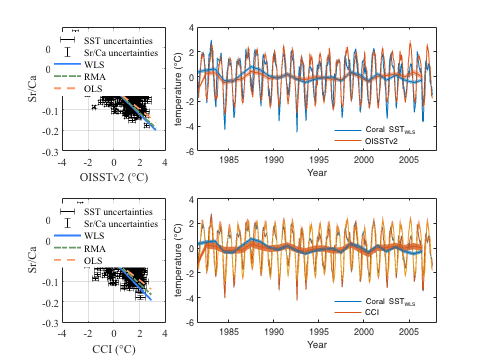

set(lg,'box','off')
xlabel('Year')

%OISSTv2
tic


tol = 1e-8;    % Tolerance
X = OISSTv2(k1:end)-mean(OISSTv2(k1:end));
sigX = OISSTv2error(k1:end);
Y = srcamonthly(k1:end)-mean(srcamonthly(k1:end));
sigY = srcaerrormonthly(k1:end);


%% 3. Simple Linear Regression
% Performs simple linear regression (SLR) for comparison.

R = corrcoef(X,Y);
n = length(X);

ri = 0;
X1 = [n,sum(X);sum(X),sum(X.*X)];               % LSE Value of 'b'
Y1 = [sum(Y);sum(X.*Y)];                        % Polyfit can also be used
Z1 = X1\Y1;                                     % Matrix division
a1 = Z1(1);
b1 = Z1(2);

sigres = sum((Y - a1 - b1.*X).^2)/(n-2);        % Sigma Residual  s^2
delta = det(X1);  % Determinant              = n*(n-1)*varx 
varx = var(X);
sigb1sq = (n^2)*(n-1)*varx*sigres/(delta^2);    % Sigma(b) without weights
sigb1 = sqrt(sigb1sq); % standard error of slope 
Xbar = mean(X);

%siga1sq = (sigres/(varx*n))*(varx + Xbar^2) 
siga1sq = sigres*(1/n + Xbar^2/varx/(n-1)); 
siga1 = sqrt(siga1sq); % standard error of intercept
A_SLR = [a1 siga1];                             % SLR Intercept
B_SLR = [b1 sigb1];                            % SLR Slope

%---- SLR p-value ----

B1 = 0;
t1=(b1-B1)/sigb1;    % t = (m - m0)/SE
Pval1=2*(1-tcdf(abs(t1),n-2)); %?

%% 4. Maximum Likelihood Method (Weighted Linear Regression)
% Implements the _York et al._ [200.00104] algorithm to perform weighted linear
% regression using the maximum likelihood method (MLM).

%---- Weighting Errors ----

wX = abs(1./(sigX.^2));                     %weights w = 1/sig^2
wY = abs(1./(sigY.^2));
alpha = sqrt(wX.*wY);
%ri = mat(:,5);         % CorrCoef between sig(X) and sig(Y)

b = b1;                             
d = tol;                            
i = 0; 

%---- York et al. (2004) Algorithm ----

while (d > tol || d == tol)         % Tolerance check loop
    i = i+1;
    b2 = b;
    W = wX.*wY./((wX) + ((b^2).*wY) - (2.*b.*alpha.*ri));
    meanX = sum(W.*X)/sum(W);       %weighted mean
    meanY =  sum(W.*Y)/sum(W);      
    U = X(:) - meanX;
    V = Y(:) - meanY;
    Beta = W.*((U./wY)+((b.*V)./wX) - (b.*U + V).*(ri./alpha));
    meanBeta = sum(W.*Beta)/sum(W);
    b = sum(W.*Beta.*V)/sum(W.*Beta.*U);
    dif = b - b2;
    d = abs(dif);
end

U2 = U.^2;
V2 = V.^2;
a = meanY - b.*meanX;
x = meanX + Beta;
meanx = sum(W.*x)/sum(W);
u = x - meanx;
sigbsq = 1./(sum(W.*(u.*u)));
sigb = sqrt(sigbsq);
sigasq = 1./(sum(W)) + meanx^2.*(sigbsq);
siga = sqrt(sigasq);
S = sum(W.*((Y - b.*X - a)).^2);

%---- MLE p-value ----
B = 0;
t=(b-B)/sigb;
Pval=2*(1-tcdf(abs(t),length(X)-2));


%RMA method
[rb,bintr,bintjm] = gmregress(X,Y,0.05)
SE = (bintr(2,2)-bintr(2,1))/3.92
SSR = sum((Y - (rb(2).*X + rb(1))).^2)
SST = sum((Y - mean(Y)).^2)
rb_r = -1*sqrt(1 - SSR/SST)
rb_r2 = 1 - SSR/SST


% regression error 
yfit = B(1).*X + A(1);
err_WLS = Y-yfit;
SSE = sum(err_WLS.^2);
MSE = SSE/(length(X)-2);
RMSE_WLS=sqrt(MSE)

err_OLS = Y - (B_SLR(1).*X + A_SLR(1));
SSE2 = sum(err_OLS.^2);
MSE2 = SSE2/(length(X)-2);
RMSE_OLS=sqrt(MSE2)


err_RMA = Y - (rb(2).*X + rb(1));
SSE3 = sum(err_RMA.^2);
MSE3 = SSE3/(length(X)-2);
RMSE_RMA=sqrt(MSE3)

figure
subplot(4,3,1)
plot(err_WLS)
title('WLS Residuals')
subplot(4,3,2) 
plot(err_RMA)
title('RMA Residuals')
subplot(4,3,3) 
plot(err_OLS)
title('OLS Residuals')


subplot(4,3,4)
histogram(err_WLS)
title('WLS Residuals Distribution')
subplot(4,3,5)
histogram(err_RMA)
title('RMA Residuals Distribution')
subplot(4,3,6)
histogram(err_OLS)
title('OLS Residuals Distribution')


subplot(4,3,7)
plot(X,err_WLS,'.')
yline(0,'--')
title('WLS Residuals vs. SST')
subplot(4,3,8)
plot(X,err_RMA,'.')
yline(0,'--')
title('RMA Residuals vs. SST')
subplot(4,3,9)
plot(X,err_OLS,'.')
yline(0,'--')
title('OLS Residuals vs. SST')

subplot(4,3,10)
autocorr(err_WLS,25)
title('WLS Residuals Autocorrelation')
subplot(4,3,11)
autocorr(err_RMA,25)
title('RMA Residuals Autocorrelation')
subplot(4,3,12)
autocorr(err_OLS,25)
title('OLS Residuals Autocorrelation')



[h,p] = adtest(err_WLS)
mean(err_WLS)

[h,p] = adtest(err_RMA)
mean(err_RMA)

[h,p] = adtest(err_OLS)
mean(err_OLS)

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat     pValue 
                   _________    _________    _______    _______

    (Intercept)       6.4791       16.836    0.38483    0.70375
    x1             0.0099818    0.0084454     1.1819    0.24882


Number of observations: 26, Error degrees of freedom: 24
Root Mean Squared Error: 0.323
R-squared: 0.055,  Adjusted R-Squared: 0.0156
F-statistic vs. constant model: 1.4, p-value = 0.249

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat      pValue 
                   ________    _________    ________    _______

    (Intercept)      1.6821       17.448    0.096404      0.924
    x1             0.012381    0.0087526      1.4145    0.17006


Number of observations: 26, Error degrees of freedom: 24
Root Mean Squared Error: 0.335
R-squared: 0.077,  Adjusted R-Squared: 0.0385
F-statistic vs. constant model: 2, p-value = 0.17

OISSTv2seasonal = table2array(seasonalmean(OISSTv2));
Yearseason = [1671:1/4:2007+1/4*3]';
OISSTv2seasonal = OISSTv2seasonal(:,2:end)';
OISSTv2seasonal=reshape(OISSTv2seasonal,4*337,1);
OISSTv2errorseasonal = table2array(seasonalerror(OISSTv2error));
OISSTv2errorseasonal = OISSTv2errorseasonal(:,2:end)';
OISSTv2errorseasonal = reshape(OISSTv2errorseasonal,4*337,1);
SrCaseasonal = table2array(seasonalmean(srcamonthly));
SrCaseasonal = SrCaseasonal(:,2:end)';
SrCaseasonal=reshape(SrCaseasonal,4*337,1);
SrCaerrorseasonal = table2array(seasonalerror(srcaerrormonthly));
SrCaerrorseasonal = SrCaerrorseasonal(:,2:end)';
SrCaerrorseasonal = reshape(SrCaerrorseasonal,4*337,1);
%match data length from 1982 to 2007
% Citation: Thirumalai, K., A. Singh, and R. Ramesh (2011), _A MATLAB code 
% to perform weighted linear regression with (correlated or uncorrelated) 
% errors in bivariate data_, Journal of the Geological Society of India, 
% 77(4), 377–380, doi: <http://is.gd/sk1hMu 10.1007/s12594-011-0044-1>.
%
%=====================================
% INPUT
%=====================================
% Excel file/array with the following format:
% 
% Column 1 | Column 2 | Column 3 | Column 4 | Column 5    |
% X data   | sigX     | Y data   | sigY     | r^2(sigmas) |

tic


tol = 1e-8;    % Tolerance
X = OISSTv2seasonal(1244:1347)-mean(OISSTv2seasonal(1244:1347));
sigX = OISSTv2errorseasonal(1244:1347);
Y = SrCaseasonal(1244:1347)-mean(SrCaseasonal(1244:1347));
sigY = SrCaerrorseasonal(1244:1347);

%% 3. Simple Linear Regression
% Performs simple linear regression (SLR) for comparison.

R = corrcoef(X,Y);
n = length(X);

ri = 0;
X1 = [n,sum(X);sum(X),sum(X.*X)];               % LSE Value of 'b'
Y1 = [sum(Y);sum(X.*Y)];                        % Polyfit can also be used
Z1 = X1\Y1;                                     % Matrix division
a1 = Z1(1);
b1 = Z1(2);

sigres = sum((Y - a1 - b1.*X).^2)/(n-2);        % Sigma Residual  s^2
delta = det(X1);  % Determinant              = n*(n-1)*varx 
varx = var(X);
sigb1sq = (n^2)*(n-1)*varx*sigres/(delta^2);    % Sigma(b) without weights
sigb1 = sqrt(sigb1sq); % standard error of slope 
Xbar = mean(X);

%siga1sq = (sigres/(varx*n))*(varx + Xbar^2) 
siga1sq = sigres*(1/n + Xbar^2/varx/(n-1)); 
siga1 = sqrt(siga1sq); % standard error of intercept
A_SLR = [a1 siga1];                             % SLR Intercept
B_SLR = [b1 sigb1];                            % SLR Slope

%---- SLR p-value ----

B1 = 0;
t1=(b1-B1)/sigb1;    % t = (m - m0)/SE
Pval1=2*(1-tcdf(abs(t1),n-2)); %?

%% 4. Maximum Likelihood Method (Weighted Linear Regression)
% Implements the _York et al._ [200.00104] algorithm to perform weighted linear
% regression using the maximum likelihood method (MLM).

%---- Weighting Errors ----

wX = abs(1./(sigX.^2));                     %weights w = 1/sig^2
wY = abs(1./(sigY.^2));
alpha = sqrt(wX.*wY);
%ri = mat(:,5);         % CorrCoef between sig(X) and sig(Y)

b = b1;                             
d = tol;                            
i = 0; 

%---- York et al. (2004) Algorithm ----

while (d > tol || d == tol)         % Tolerance check loop
    i = i+1;
    b2 = b;
    W = wX.*wY./((wX) + ((b^2).*wY) - (2.*b.*alpha.*ri));
    meanX = sum(W.*X)/sum(W);       %weighted mean
    meanY =  sum(W.*Y)/sum(W);      
    U = X(:) - meanX;
    V = Y(:) - meanY;
    Beta = W.*((U./wY)+((b.*V)./wX) - (b.*U + V).*(ri./alpha));
    meanBeta = sum(W.*Beta)/sum(W);
    b = sum(W.*Beta.*V)/sum(W.*Beta.*U);
    dif = b - b2;
    d = abs(dif);
end

U2 = U.^2;
V2 = V.^2;
a = meanY - b.*meanX;
x = meanX + Beta;
meanx = sum(W.*x)/sum(W);
u = x - meanx;
sigbsq = 1./(sum(W.*(u.*u)));
sigb = sqrt(sigbsq);
sigasq = 1./(sum(W)) + meanx^2.*(sigbsq);
siga = sqrt(sigasq);
S = sum(W.*((Y - b.*X - a)).^2);

%---- MLE p-value ----
B = 0;
t=(b-B)/sigb;
Pval=2*(1-tcdf(abs(t),length(X)-2));

%RMA method
[rb,bintr,bintjm] = gmregress(X,Y,0.05)
SE = (bintr(2,2)-bintr(2,1))/3.92
SSR = sum((Y - (rb(2).*X + rb(1))).^2)
SST = sum((Y - mean(Y)).^2)
rb_r = -1*sqrt(1 - SSR/SST)
rb_r2 = 1 - SSR/SST

%% 5. Plot
clf
hold on;
set(gca,'FontSize',12,'FontName','Myriad Pro');
h0 = errorbar(X,Y,sigX,'horizontal','Marker','none','LineStyle','none','linewidth',0.3,'Color',[0 0 0]/256);
h1 = errorbar(X,Y,sigY,'Marker','none','LineStyle','none','linewidth',0.3,'Color',[0 0 0]/256); 
%c = uisetcolor([1 1 1])
grid on;   
plot(X,Y,'.k',MarkerSize=7)
p = min(X)-(max(X)-min(X))/10:(max(X)-min(X))/10:max(X)+(max(X)-min(X))/10;
q1 = a + (b.*p);
h2 = plot(p,q1,'linewidth',2,'Color',[0.2 0.5 1]);

q2 = rb(1)+(rb(2).*p);
h3 = plot(p,q2,'-.','LineWidth',2,'Color',[0.4 0.6 0.4]);

q3 = a1 + (b1.*p);
h4 = plot(p,q3,'--','LineWidth',2,'Color',[1 0.6 0.4]);
pl = legend([h0,h1,h2,h3,h4],'SST uncertainties','Sr/Ca uncertainties','WLS','RMA','OLS');
htext=findobj(get(pl,'children'),'type','text');
set(pl,'Box','off')
set(htext,'FontName','Times New Roman','Fontsize',12);
xl = xlabel('OISSTv2 (°C)');
set(xl,'FontName','Times New Roman','FontSize',12);
yl = ylabel('Sr/Ca');
xlim([-4 4])
ylim([-0.3 0.3])
set(yl,'FontName','Times New Roman','FontSize',12);
box on


A = [a siga];
B = [b sigb];
disp('--------------------------------------');
display('Weighted Linear Regression:');disp(' ');
wr = sum(U.*V)./sqrt((sum(U2).*sum(V2)));
display('Y = a + bX');display(' ');
disp('       a      siga');disp(A);
disp('       b      sigb');disp(B);
disp(['r: ',num2str(wr)]);
disp(['r^2: ',num2str(wr^2)]);
disp(['p-value: ',num2str(Pval)]);

disp('--------------------------------------');
display('Simple Linear Regression:');disp(' ');
display('Y = a + bX');display(' ');
disp('       a      siga');disp(A_SLR);
disp('       b      sigb');disp(B_SLR);
disp(['r: ',num2str(R(1,2))]);
disp(['r^2: ',num2str(R(1,2)^2)]);
disp(['p-value: ',num2str(Pval1)]);
disp('--------------------------------------');
disp(['Total no. of iterations: ',num2str(i)]);
toc
% regression error 
yfit = B(1).*X + A(1);
err_WLS = Y-yfit;
SSE = sum(err_WLS.^2);
MSE = SSE/(length(X)-2);
RMSE_WLS=sqrt(MSE)

err_OLS = Y - (B_SLR(1).*X + A_SLR(1));
SSE2 = sum(err_OLS.^2);
MSE2 = SSE2/(length(X)-2);
RMSE_OLS=sqrt(MSE2)


err_RMA = Y - (rb(2).*X + rb(1));
SSE3 = sum(err_RMA.^2);
MSE3 = SSE3/(length(X)-2);
RMSE_RMA=sqrt(MSE3)

figure
subplot(4,3,1)
plot(err_WLS)
title('WLS Residuals')
subplot(4,3,2) 
plot(err_RMA)
title('RMA Residuals')
subplot(4,3,3) 
plot(err_OLS)
title('OLS Residuals')


subplot(4,3,4)
histogram(err_WLS)
title('WLS Residuals Distribution')
subplot(4,3,5)
histogram(err_RMA)
title('RMA Residuals Distribution')
subplot(4,3,6)
histogram(err_OLS)
title('OLS Residuals Distribution')


subplot(4,3,7)
plot(X,err_WLS,'.')
yline(0,'--')
title('WLS Residuals vs. SST')
subplot(4,3,8)
plot(X,err_RMA,'.')
yline(0,'--')
title('RMA Residuals vs. SST')
subplot(4,3,9)
plot(X,err_OLS,'.')
yline(0,'--')
title('OLS Residuals vs. SST')

subplot(4,3,10)
autocorr(err_WLS,10)
title('WLS Residuals Autocorrelation')
subplot(4,3,11)
autocorr(err_RMA,10)
title('RMA Residuals Autocorrelation')
subplot(4,3,12)
autocorr(err_OLS,10)
title('OLS Residuals Autocorrelation')

[h,p] = adtest(err_WLS)
mean(err_WLS)
[h,p] = adtest(err_OLS)
mean(err_OLS)
[h,p] = adtest(err_RMA)
mean(err_RMA)


function [b,bintr,bintjm] = gmregress(x,y,alpha)
%GMREGRESS Geometric Mean Regression (Reduced Major Axis Regression).
%   Model II regression should be used when the two variables in the
%   regression equation are random and subject to error, i.e. not 
%   controlled by the researcher. Model I regression using ordinary least 
%   squares underestimates the slope of the linear relationship between the
%   variables when they both contain error. According to Sokal and Rohlf 
%   (1995), the subject of Model II regression is one on which research and
%   controversy are continuing and definitive recommendations are difficult
%   to make.
%
%   GMREGRESS is a Model II procedure. It standardize variables before the 
%   slope is computed. Each of the two variables is transformed to have a 
%   mean of zero and a standard deviation of one. The resulting slope is
%   the geometric mean of the linear regression coefficient of Y on X. 
%   Ricker (1973) coined this term and gives an extensive review of Model
%   II regression. It is also known as Standard Major Axis.
%
%   [B,BINTR,BINTJM] = GMREGRESS(X,Y,ALPHA) returns the vector B of 
%   regression coefficients in the linear Model II and a matrix BINT of the
%   given confidence intervals for B by the Ricker (1973) and Jolicoeur and
%   Mosimann (1968)-McArdle (1988) procedure.
%
%   GMREGRESS treats NaNs in X or Y as missing values, and removes them.
%
%   Syntax: function [b,bintr,bintjm] = gmregress(x,y,alpha)
%
%   Example. From the Box 14.12 (California fish cabezon [Scorpaenichthys 
%   marmoratus]) of Sokal and Rohlf (1995). The data are:
%
%   x=[14,17,24,25,27,33,34,37,40,41,42];
%   y=[61,37,65,69,54,93,87,89,100,90,97];
%
%   Calling on Matlab the function: 
%                [b,bintr,bintjm] = gmregress(x,y)
%
%   Answer is:
%
%   b =
%      12.1938    2.1194
%
%   bintr =
%     -10.6445   35.0320
%       1.3672    2.8715
%   
%   bintjm =
%     -14.5769   31.0996
%       1.4967    3.0010
%
%   Created by A. Trujillo-Ortiz and R. Hernandez-Walls
%             Facultad de Ciencias Marinas
%             Universidad Autonoma de Baja California
%             Apdo. Postal 453
%             Ensenada, Baja California
%             Mexico.
%             atrujo@uabc.edu.mx
%
%   Copyright (C)  June 15, 2010. 
%
%   To cite this file, this would be an appropriate format:
%   Trujillo-Ortiz, A. and R. Hernandez-Walls. (2010). gmregress: 
%      Geometric Mean Regression (Reduced Major Axis Regression).  
%      A MATLAB file. [WWW document]. URL http://www.mathworks.com/
%      matlabcentral/fileexchange/27918-gmregress
%    
%   References:
%   Jolicoeur, P. and Mosimann, J. E. (1968), Intervalles de confiance pour
%              la pente de l�axe majeur d�une distribution normale 
%              bidimensionnelle. Biométrie-Praximétrie, 9:121-140.
%   McArdle, B. (1988), The structural relationship:regression in biology.
%              Can. Jour. Zool. 66:2329-2339.
%   Ricker, W. E. (1973), Linear regression in fishery research. J. Fish.
%              Res. Board Can., 30:409-434. 
%   Sokal, R. R. and Rohlf, F. J. (1995), Biometry. The principles and
%              practice of the statistics in biologicalreserach. 3rd. ed.
%              New-York:W.H.,Freeman. [Sections 14.13 and 15.7] 
%

if  nargin < 2
    error('gmregress:TooFewInputs', ...
          'GMREGRESS requires at least two input arguments.');
elseif nargin == 2
    alpha = 0.05;
end

x = x(:); y = y(:);

% Check that matrix (X) and rigth hand side (Y) have compatible dimensions
[n,ncolx] = size(x);
if ~isvector(y)
    error('gmregress:InvalidData', 'Y must be a vector.');
elseif numel(y) ~= n
    error('gmregress:InvalidData', ...
          'The number of rows in Y must equal the number of rows in X.');
end

% Remove missing values, if any
wasnan = (isnan(y) | any(isnan(x),2));
havenans = any(wasnan);
if havenans
   y(wasnan) = [];
   x(wasnan,:) = [];
   n = length(y);
end

R = corrcoef(x,y);
r = R(1,2); %correlation coefficient
s = r/abs(r); %find sign of the correlation coefficient: this former bug 
              %was efficiently corrected thanks to the valuable suggestions
              %given by Holger Goerlitz and Joel E. Cohen. Yes, a negative
              %slope are always negative!
S = cov(x,y);
SCX = S(1,1)*(n-1);
SCY = S(2,2)*(n-1);
SCP = S(1,2)*(n-1);
v = s*sqrt(SCY/SCX); %slope
u = mean(y)-mean(x)*v; %intercept
b = [u v];

%Ricker procedure
SCv = SCY-(SCP^2)/SCX;
N = SCv/(n-2);
sv = sqrt(N/SCX);
t = tinv(1-(alpha/2),n-2);
vi = v-t*sv; %confidence lower limit of slope
vs = v+t*sv; %confidence upper limit of slope
ui = mean(y)-mean(x)*vs; %confidence lower limit of intercept
us = mean(y)-mean(x)*vi; %confidence upper limit of intercept
uint = [ui us];
vint = [vi vs];
if ui > us
    uint([2 1]) = uint([1 2]);
else
end

if vi > vs
    vint([2 1]) = vint([1 2]);
else
end
bintr = [uint;vint];

%Jolicoeur and Mosimann procedure
r = R(1,2);
F =finv(1-alpha,1,n-2);
B = F*(1-r^2)/(n-2);
a = sqrt(B+1);
c = sqrt(B);
qi = v*(a-c); %confidence lower limit of slope
qs = v*(a+c); %confidence upper limit of slope
pi = mean(y)-mean(x)*qs; %confidence lower limit of intercept
ps = mean(y)-mean(x)*qi; %confidence upper limit of intercept
pint = [pi ps];
qint = [qi qs];
if pi > ps
    pint([2 1]) = pint([1 2]);
else
end

if qi > qs
    qint([2 1]) = qint([1 2]);
else
end
bintjm = [pint;qint];

return,
end

